# MATLAB大作业（COVID-19疫情数据的简要统计分析与预测）

王逸扬（19300180016）、杨耕智（19300180112）

项目的完整内容请参见[`https://github.com/maix00/StatisticsAnalysis`](https://github.com/maix00/StatisticsAnalysis).

clear; clc;
format long
path_country = './testdata/COVID19/country.csv';
path_daily = './testdata/COVID19/daily_info.csv';

### Chapter 3: 数据的缺失值处理

#### 3.2 对每日数据的缺失值探测、处理

daily_SA = StatisticsAnalysis( ...
    'TablePath', path_daily, ...
    'ImportOptions', { ...
        'VariableTypes', { ...
            'new_vaccinations', 'double', ...
            'total_vaccinations', 'double' ...
            }, ...
        'SelectedVariableNames', ...
            {'date', 'new_vaccinations', 'total_vaccinations'} ...
        }, ...
    'SelectTableOptions', { ...
        'location', 'France', ...
        'date', timerange("2020-01-01", "2020-12-31", 'closed') ...
        } ...
    );
daily = daily_SA.TimeTable;
daily2 = daily_SA.Update('ImportOptions', { ...
        'SelectedVariableNames', {'date', 'new_cases', 'total_cases'} ...
        }...
    ).TimeTable;
daily_SA.MissingValuesReport

ans = struct with fields:
            Map: [343×3 logical]
           date: {}
      new_cases: {[72 72]  [75 75]  [91 91]  [97 97]  [122 122]  [131 132]  [157 157]  [286 286]}
    total_cases: {}

MVO = { {'new_cases', 'total_cases'}, 'Increment-Addition', ...
        {'InterpolationStyle','LinearRound', ...
        'RemoveFirstRows',false,'RemoveLastRows',false}
    };
daily2 = daily_SA.Update('MissingValuesOptions', MVO).TimeTable;

daily_SA.MissingValuesReport.IA_new_cases_total_cases

ans =   TableMissingValues_IncrementAdditionMissingBlocks with properties:

              Increment: 'new_cases'
               Addition: 'total_cases'
         IncrementWhere: [0 1 0]
          AdditionWhere: [0 0 1]
    IncrementMissingMap: [343×1 logical]
     AdditionMissingMap: [343×1 logical]
     DecreasingAddition: {[71 72]  [74 75]  [90 91]  [96 97]  [121 122]  [130 131]  [131 132]  [156 157]  [285 286]}
          MissingBlocks: [8×1 struct]
        tpMissingBlocks: [8×1 struct]
    MissingBlocksGroups: [8×1 struct]

#### 3.1 对国家数据的缺失值探测

country_SA = StatisticsAnalysis( ...
    'TablePath', path_country ...
    );
% 国家表格各个变量的缺失值报告
country_SA.MissingValuesReport

ans = struct with fields:
                           Map: [229×13 logical]
                      location: {}
                     continent: {}
                    population: {[151 151]}
            population_density: {[6 6]  [25 25]  [46 46]  [68 68]  [84 84]  [103 103]  [136 136]  [149 149]  [151 151]  [163 163]  [171 171]  [174 174]  [192 192]  [199 200]  [206 206]  [223 223]  [226 226]}
                    median_age: {1×32 cell}
                 aged_65_older: {1×33 cell}
                 aged_70_older: {1×33 cell}
                gdp_per_capita: {1×30 cell}
                  male_smokers: {1×50 cell}
                female_smokers: {1×49 cell}
         cardiovasc_death_rate: {1×33 cell}
    hospital_beds_per_thousand: {1×49 cell}
               life_expectancy: {[84 84]  [103 103]  [108 108]  [151 151]  [163 163]}

% 各个国家的缺失值报告
Map = country_SA.MissingValuesReport.Map';
MissingCount = struct;
C_transpose = rows2vars(country_SA.WholeTable, 'VariableNamesSource', 'location');

for idx = 2: length(C_transpose.Properties.VariableNames)
    MissingFirstLast.(C_transpose.Properties.VariableNames{idx}) = FirstLastFindTrue(Map(:,idx-1));
    MissingCount.(C_transpose.Properties.VariableNames{idx}) = sum(Map(:,idx-1));
end
MissingFirstLast

MissingFirstLast = struct with fields:
                     Afghanistan: {[9 10]}
                         Albania: {}
                         Algeria: {}
                         Andorra: {[5 8]  [12 12]}
                          Angola: {[9 10]  [12 12]}
                        Anguilla: {[4 12]}
               AntiguaAndBarbuda: {[9 10]}
                       Argentina: {}
                         Armenia: {}
                           Aruba: {[9 12]}
                       Australia: {}
                         Austria: {}
                      Azerbaijan: {}
                         Bahamas: {}
                         Bahrain: {}
                      Bangladesh: {}
                        Barbados: {}
                         Belarus: {}
                         Belgium: {}
                          Belize: {[9 10]}
                           Benin: {}
                         Bermuda: {[5 7]  [9 10]  [12 12]}
                          Bhutan: {[9 10]}
                       

% 各个国家缺失值数量的分布图
MissingCount = struct2table(MissingCount);
MissingCount = MissingCount{1,:};
sum(MissingCount == 0)

ans =    128

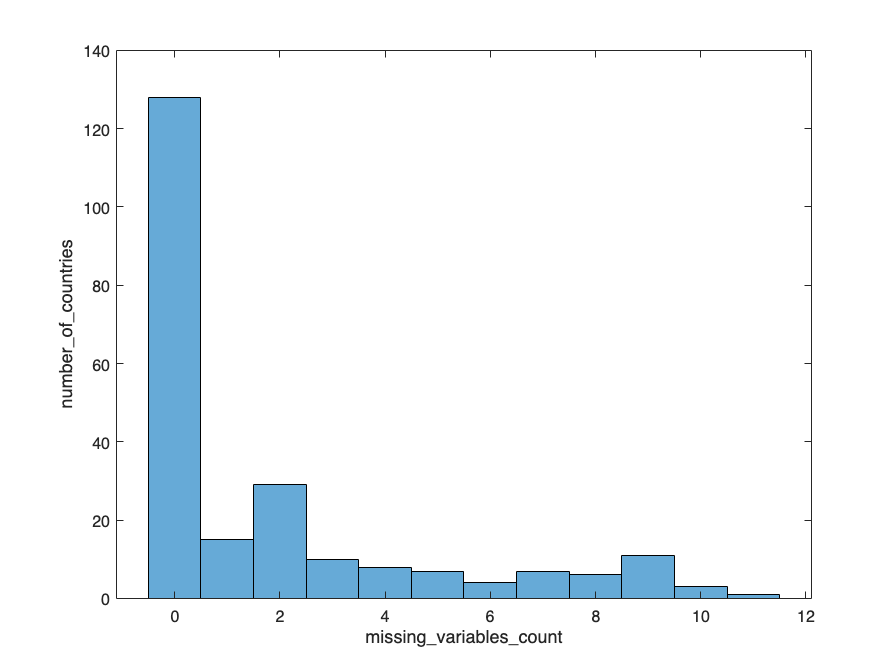

histogram(MissingCount);
xlabel('missing\_variables\_count'); ylabel('number\_of\_countries');